# PCA example

Small exercise with PCA

## Generate sample elliptical cloud of data-poitns.

At first we reset the random number generator

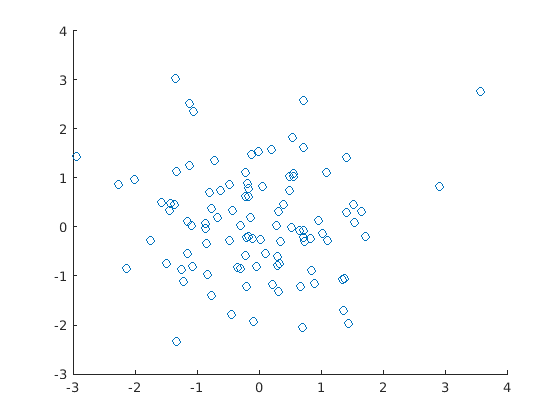

stream = RandStream.getGlobalStream;
reset(stream);
% then we generate some points
x = randn(2,100);
scatter(x(1,:),x(2,:))

## Change the spread in the second coordinate

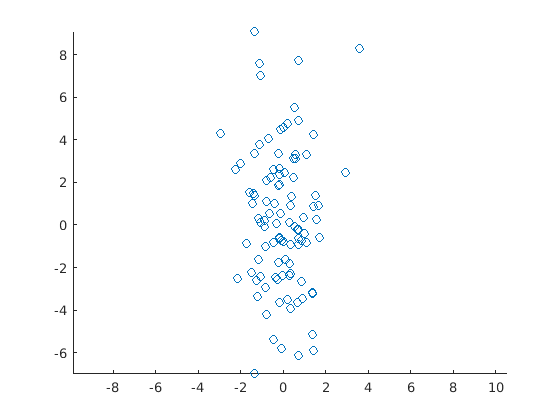

x(2,:) = 3*x(2,:);
scatter(x(1,:),x(2,:))
axis equal; % udela obe osy ve stejnem meritku?

## Rotate the cloud for demonstration.

[p(1,:),p(2,:)] = cart2pol(x(1,:),x(2,:));
p(1,:) = p(1,:)-pi/3; % rotate by sixty degrees
[x(1,:),x(2,:)] = pol2cart(p(1,:),p(2,:));

## Plot data.

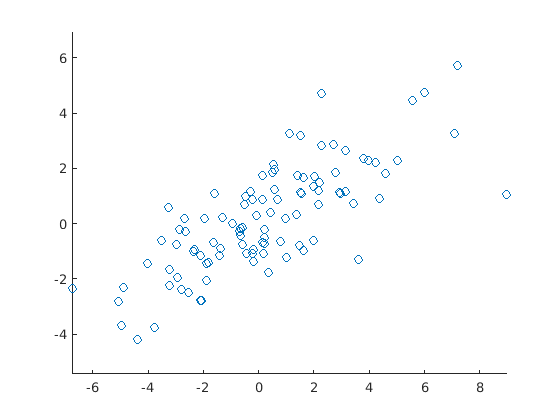

scatter(x(1,:),x(2,:)); % plot it again .. now rotated
axis equal; 

## PCA - TODO

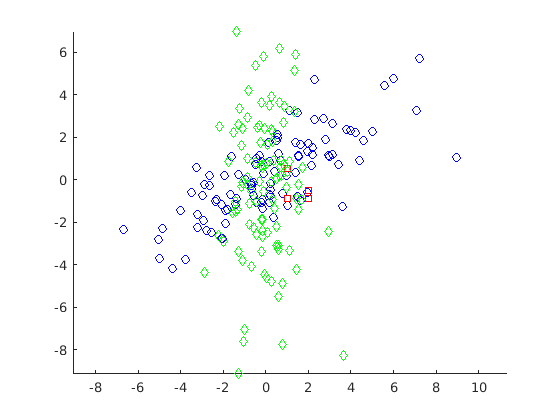

% # using functions `pcacov` and `cov` or other MATLAB functions compute Karhunen-Loeve 
% transform
% # plot the principal compoinents over the data
% # rotate the data to the princopal components
% # recompute pca to shoiw that the principal components are aligned with axes
hold on
scatter(x(1,:),x(2,:), "ob"); % blue circles
axis equal;
[V,D] = eig(cov(x'));
plot(V,"sr") % red quares
x_new = x'*V;
scatter(x_new(:,1),x_new(:,2),"dg"); % green diamods
hold off;

% we can see that the plot is for some reason flipped vertically....
% we fucked up something?
% so there are just flipped sides ...
% but after transformations coors should be spread such
% a way that first coord is more important

## Inverse transform

Set the second component of y to zero, reducing the dimensionality to one.

y(2,:) = 0;
% Transform back to the original data.

x = (y'*inv(pc))';

## Plot data.

figure;
scatter(x(1,:),x(2,:));
axis equal;